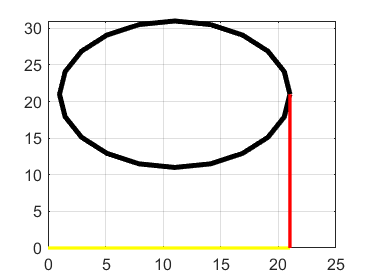

clear;clc;close all
P = [11 21];
r = 10;
L1 = 21;
L2 = 21;
xp = P(1);
yp = P(2);
Ri = sqrt(xp^2+yp^2);
Rf = Ri + r;
if Rf > (L1+L2)
    fprintf('Some of the points on the circle are non-reachable\n');
end
alpha = 0:2*pi/20:2*pi;
x = xp + r*cos(alpha);
y = yp + r*sin(alpha);

for i = 1:1:length(x)
    plot(x,y,'k','linewidth',3);grid
    R(i) = sqrt(x(i)^2+y(i)^2);
    th2(i) = acos((R(i)^2 - L1^2 - L2^2)/(2*L1*L2));
    psi(i) = atan(y(i)/x(i));
    phi(i) = acos((R(i)^2 + L1^2 - L2^2)/(2*R(i)*L1));
    th1(i) = psi(i) - phi(i);
    
    link1x(i,:) = [0:0.2:L1]*cos(th1(i));
    link1y(i,:) = [0:0.2:L1]*sin(th1(i));
    link2x(i,:) = [0:0.2:L2]*cos(th1(i)+th2(i))+L1*cos(th1(i));
    link2y(i,:) = [0:0.2:L2]*sin(th1(i)+th2(i))+L1*sin(th1(i));
    hold on
    plot(link1x(i,:),link1y(i,:),'y','linewidth',2);
    hold on;
    plot(link2x(i,:),link2y(i,:),'r','linewidth',2)
    pause(0.2)
    hold off
end